# **Full State Feedback Control**

## **System:** *Control of Inverted Pendulum and Cart*

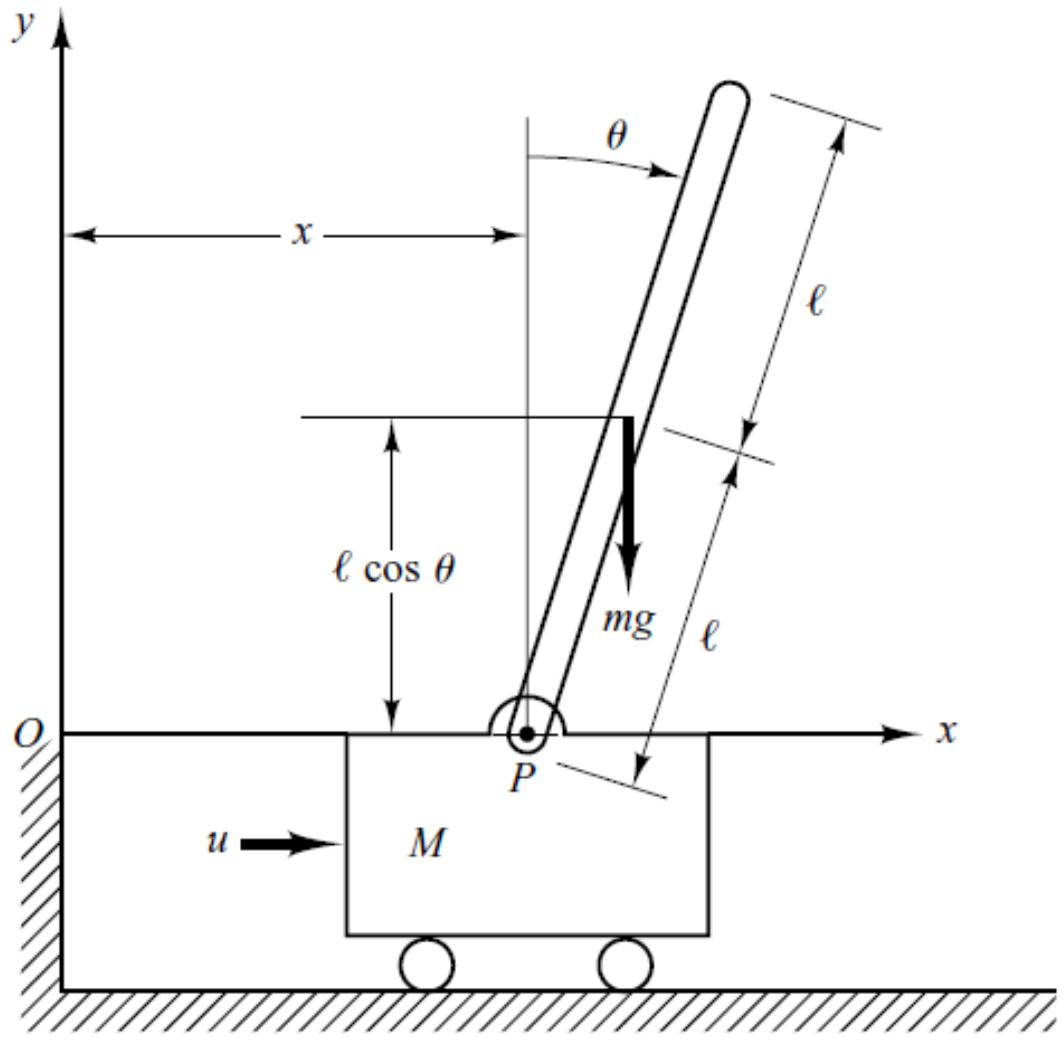

#### Model Parameters

clear;
clc;
g=9.81;
l=0.5;
m=0.3;
M=2.3;
J=1/3*m*(2*l)^2;
z=M*J+m*M*l^2+m*J;

#### Model of Inverted Pendulum

A=[0 1 0 0;
    ((M+m)*m*g*l)/z 0 0 0;
    0 0 0 1;
    -m^2*l^2*g/z 0 0 0];
B=[0; -m*l/z; 0; (J+m*l^2)/z];
C=[1 0 0 0;
   0 1 0 0;
   0 0 1 0;
   0 0 0 1];
D=0;
sys=ss(A,B,C,D);

#### Model Control Ability and Observeability

P_o=obsv(sys);
P_c=ctrb(sys);

if(rank(P_o)~=4)
    disp('System is not Observeable');
else
    disp('System is Observeable');
end

System is Observeable



if(rank(P_c)~=4)
    disp('System is not Controlable');
else
    disp('System is Controlable');
end

System is Controlable


#### System Stability Analysis

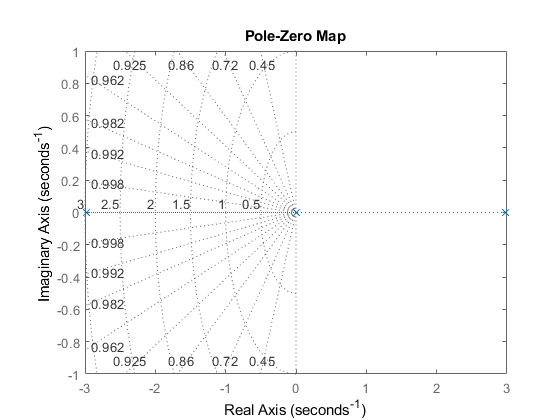

pole_Open=pole(sys);
figure(1);
pzplot(sys); grid on;

#### Response of System

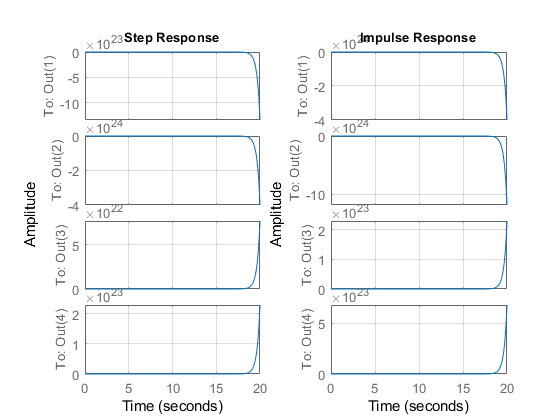

figure(2);
subplot(1,2,1);
step(sys); grid on;
step_Param=stepinfo(sys);

subplot(1,2,2);
impulse(sys); grid on;

#### Pole Placement

zeta=0.9;
T_s=1.33;
w_n=4/(zeta*T_s);
syms s;
eq=s^2+2*zeta*w_n*s+w_n^2==0;
root=simplify(solve(eq,{'s'}));
pol_Des=[double(real(root(1)))+double(imag(root(1)))*1i;
    double(real(root(2)))+double(imag(root(2)))*1i;
    5*double(real(root(1)))+0.1i;
    5*double(real(root(1)))-0.1i];
K=place(A,B,pol_Des);

#### Response to Initial Conditions

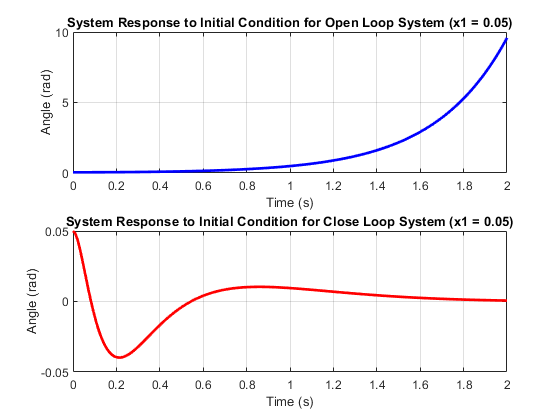

t=(0:0.01:2)';
sys_Close=ss(A-B*K,[],C,[]);
sys_Open=ss(A,[],C,[]);

ini_Cond=[0.05;0;0;0];

x_Open=initial(sys_Open,ini_Cond,t);
x_Close=initial(sys_Close,ini_Cond,t);

figure(3);
subplot(2,1,1);
plot(t,x_Open(:,1),'-b','linewidth',2); grid on;
title('System Response to Initial Condition for Open Loop System (x1 = 0.05)');
xlabel('Time (s)');
ylabel('Angle (rad)');

subplot(2,1,2);
plot(t,x_Close(:,1),'-r','linewidth',2); grid on;
title('System Response to Initial Condition for Close Loop System (x1 = 0.05)');
xlabel('Time (s)');
ylabel('Angle (rad)');

#### Plotting Input for Close Loop System

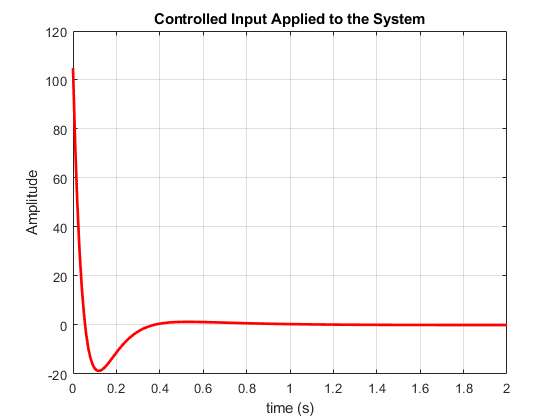

U=(-K*x_Close')';
figure(4);
plot(t,U,'-r','LineWidth',2); grid on;
title('Controlled Input Applied to the System');
xlabel('time (s)');
ylabel('Amplitude');

#### Open Loop Animation

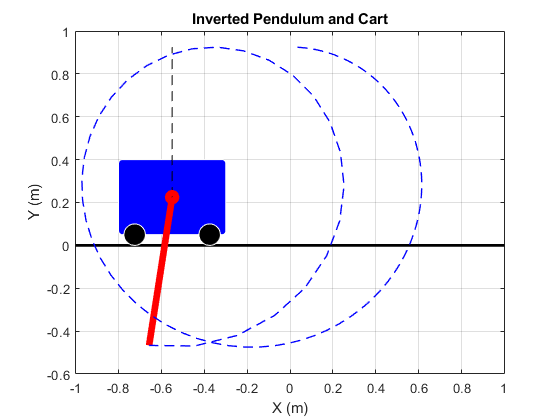

figure(5);
animate(x_Open(:,1),x_Open(:,3),5);

#### Close Loop Animation

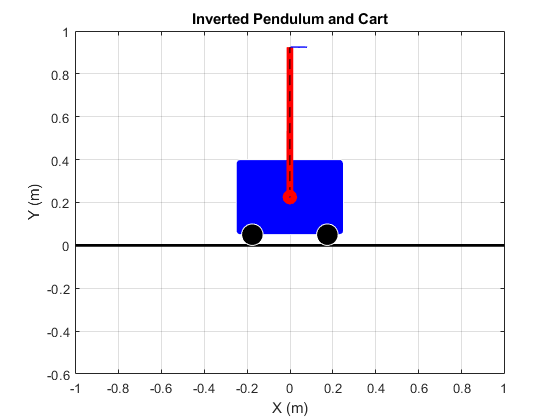

figure(6);
animate(x_Close(:,1),x_Close(:,3),6);

#### Animation Function

function animate(th,d,n)
W  = 0.5;
H  = 0.35;
L  = 0.7;
wr = 0.1;

for i=1:length(d)
    y = H/2+wr/2;
    w1x = d(i)-0.9*W/2;
    w1y = 0;
    w2x = d(i)+0.9*W/2-wr;
    w2y = 0;
    
    px = d(i) + L*sin(th(i));
    py = y + L*cos(th(i));
    
    pjx(i) = px;
    pjy(i) = py;
    
    figure(n);
    base = plot([-100 100],[0 0],'k','LineWidth',2); % base line
    hold on;
    grid on;
    
    xlabel('X (m)');
    ylabel('Y (m)');
    title('Inverted Pendulum and Cart');
    axis(gca,'equal');
    
    if(i==1)
        x_lim=[-1 1];
        y_lim=[-0.6 1];
        mul=1;
    end
    
    if(d(i)-W/2<=x_lim(1) || d(i)-W/2>=x_lim(2))
        x_lim=2*x_lim;
        y_lim=2*y_lim;
        mul=mul*2;
    end
    xlim(x_lim);
    ylim(y_lim);
    
    cart = rectangle('Position',[d(i)-W/2,y-H/2,W,H],'Curvature',0.1/mul,'FaceColor',[0 0 1],'EdgeColor',[1 1 1]);
    left_wheel  = rectangle('Position',[w1x,w1y,wr,wr],'Curvature',1/mul,'FaceColor',[0 0 0],'EdgeColor',[1 1 1]);
    right_wheel = rectangle('Position',[w2x,w2y,wr,wr],'Curvature',1/mul,'FaceColor',[0 0 0],'EdgeColor',[1 1 1]);
    
    pendulum = plot([d(i) px],[y py],'r','LineWidth',5/mul);
    dot_line = plot([d(i) d(i)],[y y+L],'--k','LineWidth',0.1/mul);
    p_cir1 = plot(d(i),y,'or','LineWidth',5/mul);
    line_traj = plot(pjx(1:i),pjy(1:i), '--b','LineWidth',1/mul);
    
    if(i==1)
        pause(3-0.01);
    end
    pause(0.01);
    hold off;
end
end